Settings for scripts

clear
% import con1-6
numcondition = 6;
proname   = 'WBP2 VASP PY mut n3';
con1title = 'MDA-MB231 pcDNA/GFP -CL';
con2title = 'MDA-MB231 pcDNA/GFP +CL';
con3title = 'MDA-MB231 WT WBP2/GFP +CL';
con4title = 'MDA-MB231 WT WBP2/WT VASP +CL';
con5title = 'MDA-MB231 PY1 WBP2/WT VASP +CL';
con6title = 'MDA-MB231 WT WBP2/S239A VASP +CL';
videoname = strcat(proname, 'new.avi');
imagename = strcat(proname, 'new.tif');
fminame   = strcat(proname, 'FMI new.tif');
wsname    = strcat(proname, '.mat');
timeint = 15; %time interval between frame in min
pxsize = 0.627;  %pixel size in um
numframe=40;
framerate = 2;
currfd = pwd;

Importing Data

contitle = {con1title, con2title, con3title, con4title, con5title, con6title};
datacon = cell(1,numcondition);
for i = 1:numcondition   
    conname = strcat('con', int2str(i), '*');
    datacon{i} = imcon(currfd,conname);
    disp(i)
end
disp('data import done')

Data cleaning

%Data cleaning (remove outlier and fixed last point)

     1

     2

     3

     4

     5

     6



for i = 1:numcondition

data import done


    tempdata = cell2mat(datacon(i));
    tempdata = dataclean(tempdata,numframe);
    datacon{i} = tempdata;
    disp(i)
end

disp('data cleaning done')


     1

     2

     3

     4

     5

     6



Calculating endpoint parameters

%Calculate FMI
fminum = 40;

data cleaning done


for i = 1:numcondition
    tempdata = cell2mat(datacon(i));
    [fmioutput{i},dispoutput{i},distoutput{i},veloutput{i}] = fmi(tempdata,fminum, pxsize, timeint);
    deltadeg{i} = deltadegree(tempdata,fminum);
end
disp('Endpoint parameter calculation done')

Finding minimum number of cells in each conditions and setting the appropriate limit for the plot

%Finding limits and minimum num cells
limit = 0;

Endpoint parameter calculation done


mincell = Inf;
for i = 1:numcondition
    tempdata = cell2mat(datacon(i));
    newlimit = max(abs(tempdata(:)));
    if newlimit > limit
        limit = newlimit;
    else
        %do nothing
    end
    
    newmincell = size(tempdata,3);
    if newmincell < mincell
        mincell = newmincell;
    else
        %do nothing
    end    
end

Output for FMI, Distance, and DIsplacement

%Output compile FMI Dist and Displcement
[FMIout, Dispout, Distout, Deltadegout, Velout] = deal(zeros(mincell,numcondition));
for i = 1:numcondition
    tempdata = cell2mat(fmioutput(i));  FMIout(:,i) = tempdata(1:mincell);
    tempdata = cell2mat(dispoutput(i)); Dispout(:,i) = tempdata(1:mincell);
    tempdata = cell2mat(distoutput(i)); Distout(:,i) = tempdata(1:mincell);
    tempdata = cell2mat(deltadeg(i)); Deltadegout(:,i) = tempdata(1:mincell);
    tempdata = cell2mat(veloutput(i)); Velout(:,i) = tempdata(1:mincell);
end


Drawing animinated plot and FMI plot

% STEP 1:
%
% Create and open the video object
    vidObj = VideoWriter(videoname);
    vidObj.FrameRate=framerate;
    open(vidObj);
%
% Loop over the data to create the video
f1 = figure('Position',[10 10 800 900]);
for i= 1:numframe
   % Plot the data
   clf(f1,'reset')
   tic
   time = strcat(int2str(i*timeint),' min');
   
   for j = 1:numcondition
        tempdata = cell2mat(datacon(j));
        tempcontitle = string(contitle(j));
        subplot(3,2,j)
        plotgraph(tempdata,tempcontitle,mincell,limit,i,time)
   end

   % STEP 2
   %
   % Get the current frame
   currFrame = getframe(f1);
   
   % STEP 3
   %
   % Write the current frame
   writeVideo(vidObj,currFrame);
   %
   
   %Step 4
   %Save last frame as image
   if i == numframe
       saveas(f1,imagename);
   end
%   
   
   timerem = toc;
   disp('Time left (min)')
   disp((numframe-i)*timerem/60)
end

Time left (min)


    3.3557



Time left (min)


    2.7779



Time left (min)


    2.5786



Time left (min)


    2.3160



Time left (min)


    2.3673



Time left (min)


    2.1506



Time left (min)


    2.1897



Time left (min)


    2.0075



Time left (min)


    2.0087



Time left (min)


    1.9033



Time left (min)


    1.9346



Time left (min)


    1.7695



Time left (min)


    1.6942



Time left (min)


    1.7884



Time left (min)


    1.5886



Time left (min)


    1.5565



Time left (min)


    1.5284



Time left (min)


    1.7053



Time left (min)


    1.4196



Time left (min)


    1.4579



Time left (min)


    1.3121



Time left (min)


    1.1640



Time left (min)


    1.1359



Time left (min)


    1.0266



Time left (min)


    1.0702



Time left (min)


    0.9121



Time left (min)


    0.8315



Time left (min)


    0.7717



Time left (min)


    0.7302



Time left (min)


    0.6477



Time left (min)


    0.5867



Time left (min)


    0.5096



Time left (min)


    0.4719



Time left (min)


    0.3939



Time left (min)


    0.3210



Time left (min)


    0.2536



Time left (min)


    0.1958



Time left (min)


    0.1285



Time left (min)


    0.0643



Time left (min)


     0




% STEP 4

% Close (and save) the video object
close(vidObj);


f2 = figure;
   for i = 1:numcondition
        tempdata = cell2mat(datacon(i));
        fmigraph(tempdata,numframe)
   end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


   legend(contitle,'Location','northeast')
   saveas(f2,fminame)


   
disp('saving workspace')

saving workspace


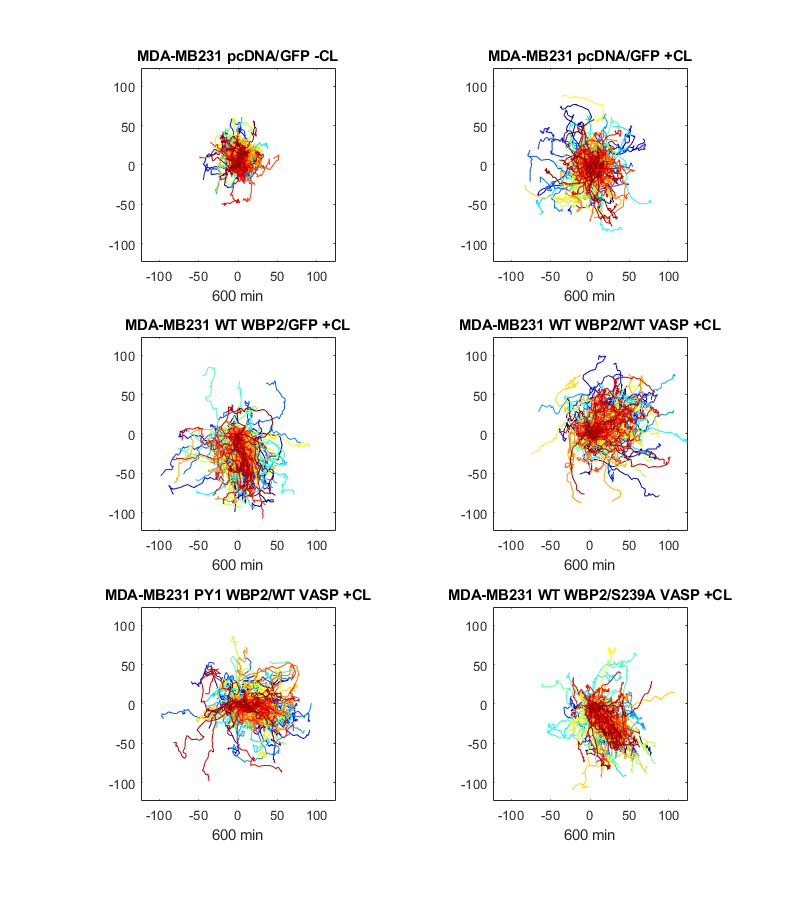

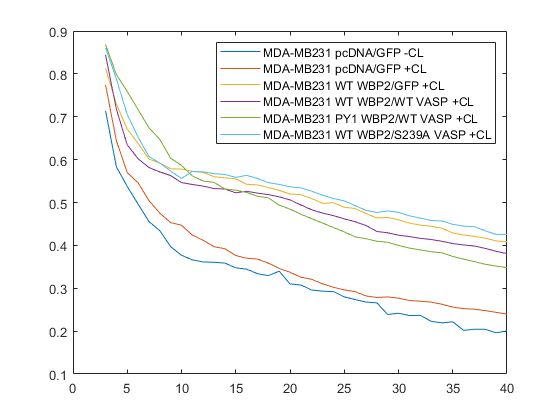

    
save(wsname);

    
disp('Done');

Done


Functions

function dataoutput = dataclean(datainput,timesize)
    %Remove outlier
    datacon = datainput(1:timesize,:,:);
    maxcon = max(abs(datacon),[],1);
    maxdisp = zeros(size(maxcon,3),1);
    for i = 1:size(maxcon,3)
        maxdisp(i) = norm(maxcon(:,:,i));
    end
    logi = isoutlier(maxdisp);
    tempoutput = datainput(1:timesize,:,:);
    tempoutput(:,:,logi)=[];
    
    logi = isnan(tempoutput);
    tempoutput(logi)=0;
    
    %Remove those that havent reach last timepoint  
    samplesize = size(tempoutput,3);
    logi = zeros(samplesize,1);
    for k = 1:samplesize
       if tempoutput(timesize,:,k)==[0,0]
           logi(k)=1;
       end
    end
    logi = logi==1;
    tempoutput(:,:,logi)=[];
    
    %Fixed last point position
    samplesize = size(tempoutput,3);
    for k = 1:samplesize
        for i = 2:timesize
            if tempoutput(i,:,k) == [0,0]
                tempoutput(i,:,k) = tempoutput(i-1,:,k);
            end
        end
    end
    dataoutput = tempoutput;
end


function plotgraph(plotdata,contitle,numcell,limit,currframe,currtime)
    c=jet(numcell);
    
    for j=1:numcell
        h1=plot(plotdata(1:currframe,1,j),plotdata(1:currframe,2,j));
        h1.Color = c(j,:);
        hold on
    end
    
    xlim([-limit limit])
    ylim([-limit limit])
    axis square
    title(contitle)
    xlabel(currtime)
    hold off
end

function [fmiout,dispout, distout, velout] = fmi(datacon,timesize, pxsize, timeint)
    if ~exist('pxsize','var') %check if pxsize exist
        pxsize = 0.627;
    end
    if ~exist('timeint','var') %check if pxsize exist
        timeint = 15;
    end
    datasize = size(datacon,3);
    displ = zeros(timesize,datasize);
    for k = 1:datasize
        for i = 2:timesize
            temphold = [datacon(i-1,:,k);datacon(i,:,k)];
            displ(i,k) = pdist(temphold);
        end
    end
    fmiout = zeros(datasize,1);
    dispout = zeros(datasize,1);
    distout = zeros(datasize,1);
    velout = zeros(datasize,1);
    for j = 1:datasize
       tdist = sum(displ(:,j));
       tdispl = pdist([ 0 0; datacon(timesize,:,j)]);
       fmiout(j) = tdispl ./ tdist; 
       dispout(j) = tdispl;
       distout(j) = tdist;
       velout(j) = tdist * pxsize / (timesize * timeint); %Calculate final velocity in um/min
   end
end

function datacon=imcon(currfd,cname)
    filename = dir(fullfile(currfd,cname));
    condata = xlsread(filename.name);
    datacon=zeros(size(condata,1),2,size(condata,2)/4);
    for i = 1:size(datacon,3)
        datacon(:,:,i)=condata(:,i*4-3:i*4-2);
    end
end

function fmigraph(datacon,numframe)
    fmipara = zeros(numframe,2);
    parfor i = 1:numframe
        fmiout = fmi(datacon,i);
        meanfmi = mean(fmiout);
        sdfmi = std(fmiout);
        fmipara(i,:)= [meanfmi,sdfmi];
    end
    x = 1:numframe;
    plot(x,fmipara(:,1))
    hold on
end

function dirdegree = dirdeg(pos1,pos2)
    y = pos1(1) - pos2(1);
    x = pos1(2) - pos2(2);
    dirdegree = rad2deg(atan(y/x));
    if y >= 0
        if x  >= 0
            dirdegree = 0 + dirdegree;
        elseif x < 0
            dirdegree = 180 + dirdegree;
        end
    elseif y < 0
        if x  >= 0
            dirdegree = 360 - dirdegree;
        elseif x < 0
            dirdegree = 180 + dirdegree;
        end
    end
end

function deltadeg = deltadegree(datacon,timesize)
    datasize = size(datacon,3);
    deltadeg = zeros(datasize,1);
    tempdeg = zeros(timesize-2,1);
    for j = 1:datasize
        for i = 1:timesize-2
            tempdeg(i) = dirdeg(datacon(i+1,:,j),datacon(i+2,:,j)) - dirdeg(datacon(i,:,j),datacon(i+1,:,j));
            if isnan(tempdeg(i))
                tempdeg(i) = 180;
            elseif abs(tempdeg(i)) > 180
                tempdeg(i) = 360 - abs(tempdeg(i));
            else
                tempdeg(i) = abs(tempdeg(i));
            end
        end
        deltadeg(j) = mean(tempdeg);
    end
end